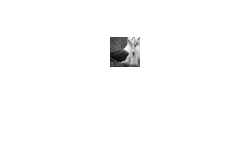

[filename,filepath]=uigetfile('.jpg','输入一个图像');% read a picture
file=strcat(filepath,filename); 
IMG=imread(file);
IMG = double(rgb2gray(IMG));% Convert to gray image

m = 30;
n = 30;
I = imresize(IMG,[m,n]);% resize to be easy to verify. Also can be [30 10]
imshow(mat2gray(I));


X = fft2(I);

% create gaussian labels 
sigma = 0.01;
[rs, cs] = ndgrid((1:m) - floor(m/2), (1:n) - floor(n/2));
g = exp(-0.5 / sigma^2 * (rs.^2 + cs.^2));
G = fft2(g);

[V_col,I_col] = max(g);
[V,I_row] = max(V_col);
loc = [I_col(I_row),I_row]

loc =     15    15


imagesc(g)


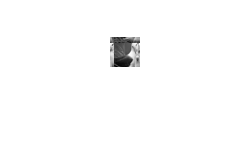

%simulate a traslated sample
z = circshift(I,[6,4])+1e-5*rand(m,n);
imshow(mat2gray(z));

Z = fft2(z);

%MOSSE

%caculate H*
H_conj = G./X;
h = real(ifft2(conj(H_conj)));
imagesc(h)


RES = Z.*H_conj;
res = real(ifft2(RES));
[V_col,I_col] = max(res);
[V,I_row] = max(V_col);
loc = [I_col(I_row),I_row]-[floor(m/2),floor(n/2)]

loc =      6     4


imagesc(res)


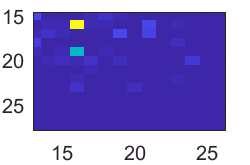

%KCF
imagesc(g)

g = circshift(g, (- floor([m n] / 2 )+ 1));
imagesc(g)


G = fft2(g);

%linear model
lambda = 1e-4;
kf = (X .* conj(X)) / numel(X);
alphaf = G ./ (kf + lambda);
imagesc(log10(real(alphaf)+1))

%model_xf = X;
%detect
kzf =(Z .* conj(X)) / numel(X);
response = real(ifft2(alphaf.*kzf));
imagesc(response)

[Locy, Locx] = find(response == max(response(:)), 1)

Locy = 7

Locx = 5